# **三维矢量场的旋度演示**

**        对于三维函数，可以用curl函数取旋度，从而得到旋度函数；使用pcolor函数绘制旋度。**

- **定义函数**

syms x y z real	%定义符号变量
a=2;
b=1;
c=1;
d=-1;
F = [ cos(a*x+b*y), sin(c*x+d*y) ]	

$$F = \left(\begin{array}{cc} \cos\left(2\,x+y\right) & \sin\left(x-y\right) \end{array}\right)$$

- **使用curl函数取散度**

G = curl([F,0],[x y z])   %计算F的旋度，并赋予G   	

$$G = \left(\begin{array}{c} 0\\ 0\\ \cos\left(x-y\right)+\sin\left(2\,x+y\right) \end{array}\right)$$

curlF=matlabFunction(G(3));	%将G的z分量，赋予curlF

- **定义网格**

x=linspace(-2.5,2.5,20);	
[X,Y]=meshgrid(x,x);	%定义网格

- **使用pcolor函数绘制旋度分布**

rot=curlF(X,Y);	%计算旋度的值
pcolor(X,Y,rot); %绘制旋度
shading interp;	%颜色做插值

- **绘制函数的矢量分布**

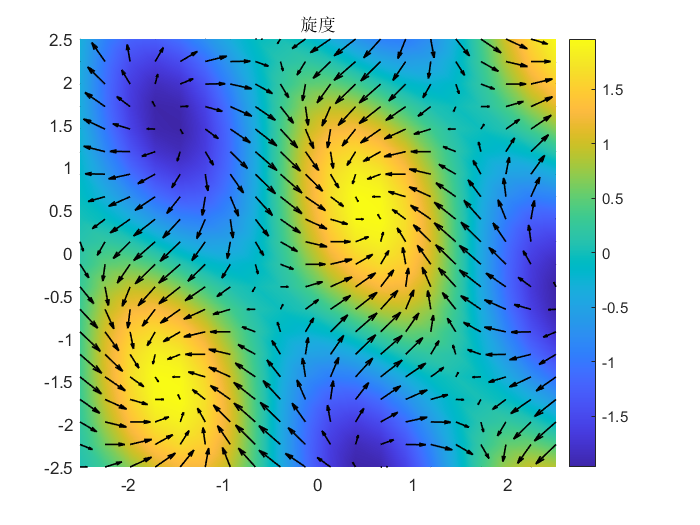

Funcx=matlabFunction(F(1));	%F的x分量
Funcy=matlabFunction(F(2));	%F的y分量
Fx=Funcx(X,Y);
Fy=Funcy(X,Y);
% Fx=cos(X+2*Y);	%计算F的x分量
% Fy=sin(X-2*Y);	%计算F的y分量
colorbar;	%绘制色条
hold on;	%保持模式打开
quiver(X,Y,Fx,Fy,'k','linewidth',1);	%绘制箭头图，并设置颜色为黑色，线宽为1
title('旋度')
set(gcf,'Visible','on');   	    %强制图片弹出显示